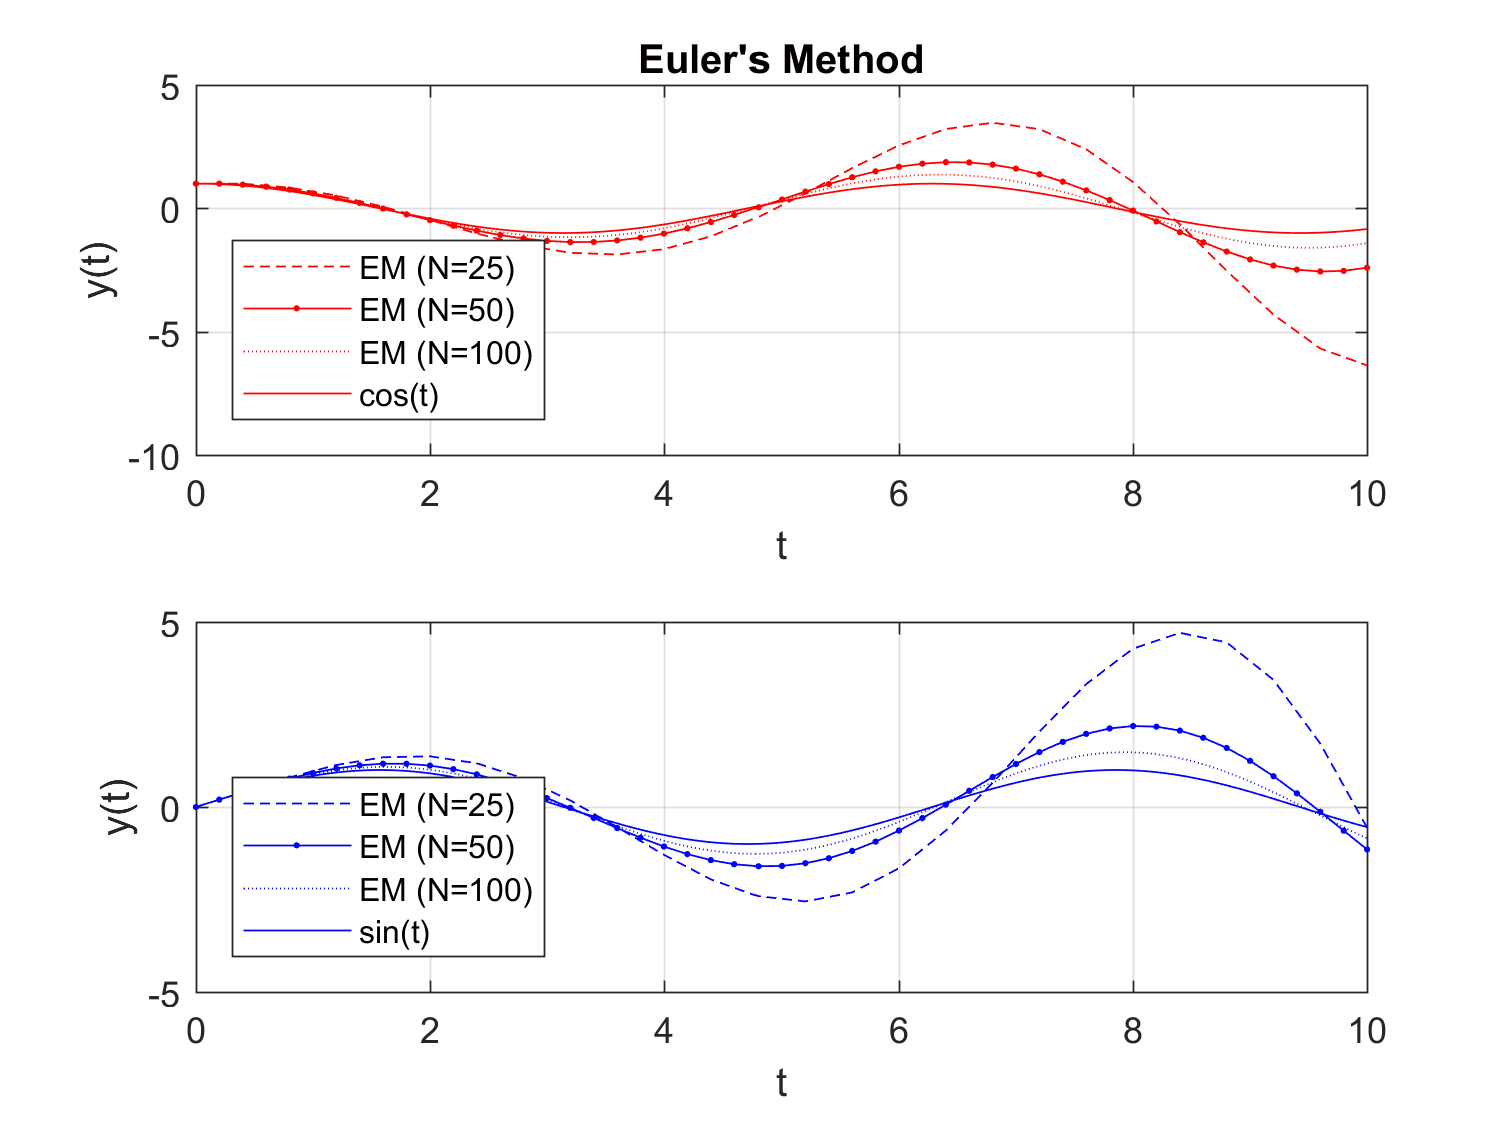

%ESC103 Lab 2
%Clean up our workspace
clear; close all; clc;
%Set problem constants
e = 0; f = -1;
g = 1; h = 0;
j = 1; k = 0;
%Set integration constants
T = 10;
%Evaluate EM and IEM for 3 different N values
N_1 = 25; N_2 = 50; N_3 = 100;
[x_em_1, y_em_1, t_em_1] = EMSolver(e,f,g,h,j,k,T,N_1);
[x_em_2, y_em_2, t_em_2] = EMSolver(e,f,g,h,j,k,T,N_2);
[x_em_3, y_em_3, t_em_3] = EMSolver(e,f,g,h,j,k,T,N_3);
[x_iem_1, y_iem_1, t_iem_1] = IEMSolver(e,f,g,h,j,k,T,N_1);
[x_iem_2, y_iem_2, t_iem_2] = IEMSolver(e,f,g,h,j,k,T,N_2);
[x_iem_3, y_iem_3, t_iem_3] = IEMSolver(e,f,g,h,j,k,T,N_3);
%Plot EM Solutions
%Time vector for exact solution
t_exact = 0:0.01:T;
%Plot x(t) vs t
subplot(2,1,1)
plot(t_em_1, x_em_1, '--r')
hold on
plot(t_em_2, x_em_2, '.-r')
plot(t_em_3, x_em_3, ':r')
plot(t_exact, cos(t_exact), '-r')
%Annotations
legend('EM (N=25)','EM (N=50)', 'EM (N=100)', 'cos(t)', 'Location', 'Southwest')
ylabel('y(t)')
xlabel('t')
title('Euler''s Method')
grid on
subplot(2,1,2)
%Plot y(t) vs t
plot(t_em_1, y_em_1, '--b')
hold on
plot(t_em_2, y_em_2, '.-b')
plot(t_em_3, y_em_3, ':b')
plot(t_exact, sin(t_exact), '-b')
%Annotations
legend('EM (N=25)','EM (N=50)', 'EM (N=100)', 'sin(t)', 'Location', 'Southwest')
ylabel('y(t)')
xlabel('t')
grid on

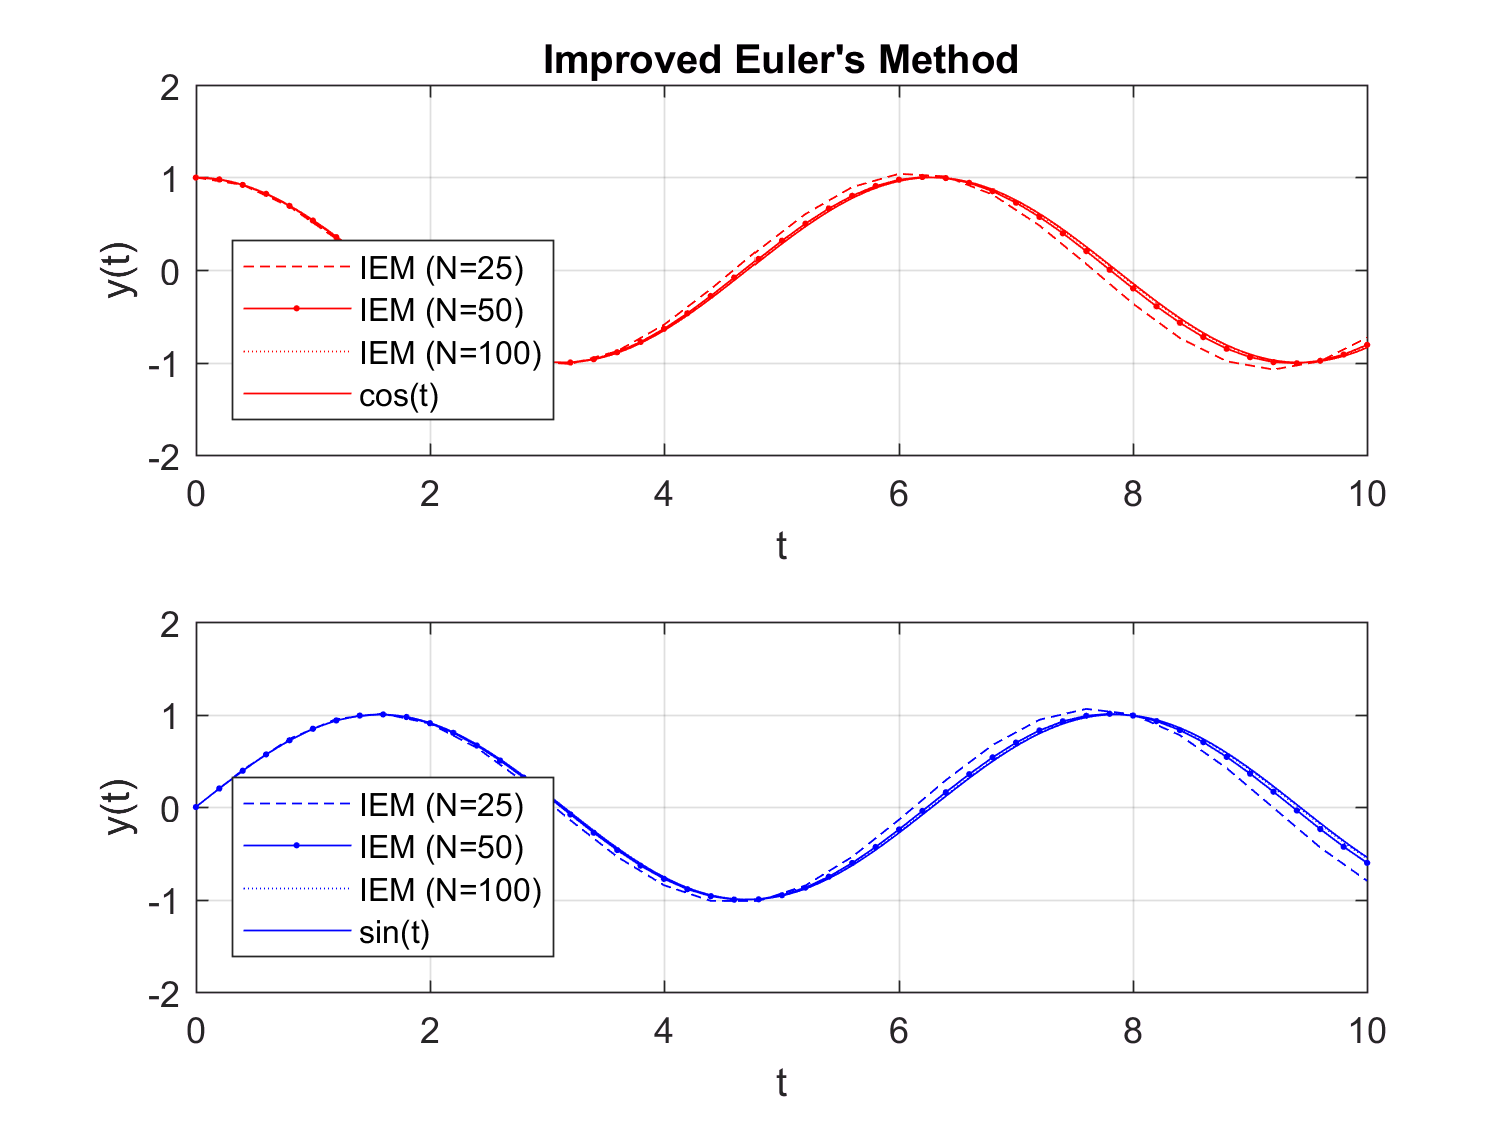

%Plot IEM Solutions
t_exact = 0:0.01:T;
figure
%Plot x(t) vs t
subplot(2,1,1)
plot(t_iem_1, x_iem_1, '--r')
hold on
plot(t_iem_2, x_iem_2, '.-r')
plot(t_iem_3, x_iem_3, ':r')
plot(t_exact, cos(t_exact), '-r')
%Annotations
legend('IEM (N=25)','IEM (N=50)', 'IEM (N=100)', 'cos(t)', 'Location', 'Southwest')
ylabel('y(t)')
xlabel('t')
title('Improved Euler''s Method')
grid on
%Plot y(t) vs t
subplot(2,1,2)
plot(t_iem_1, y_iem_1, '--b')
hold on
plot(t_iem_2, y_iem_2, '.-b')
plot(t_iem_3, y_iem_3, ':b')
plot(t_exact, sin(t_exact), '-b')
%Annotations
legend('IEM (N=25)','IEM (N=50)', 'IEM (N=100)', 'sin(t)', 'Location', 'Southwest')
ylabel('y(t)')
xlabel('t')
grid on

function [x, y, t] = IEMSolver(e,f,g,h,j,k,T,N)
%Improved Euler method integration for IVPs
 A = [e f; g h];
 dt = T/N;
 t = 0:dt:T;
 SOL = NaN(2,length(t));
 SOL(1,1) = j;
 SOL(2,1) = k;
for k = 2:length(t)
 %EM Solution (temporary variable) 
 EM = SOL(:,k-1) + dt*A*SOL(:,k-1);
 %IEM Solution
 SOL(:,k) = SOL(:,k-1) + dt/2*(A*SOL(:,k-1) + A*EM);
end
 x = SOL(1,:);
 y = SOL(2,:);
end
function [x, y, t] = EMSolver(e,f,g,h,j,k,T,N)
%Euler method integration for IVPs
 A = [e f; g h];
 dt = T/N;
 t = 0:dt:T;
 SOL = NaN(2,length(t));
 SOL(1,1) = j;
 SOL(2,1) = k;
for k = 2:length(t)
 SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
end
 x = SOL(1,:);
 y = SOL(2,:);
end 